% Script de visualización del radar CW-FM
% Generado automáticamente por testbench
clear; clc; close all;

% Parámetros del sistema
f_clk = 300000000; % Hz
f_start = 1e+09; % Hz
f_stop = 3e+09; % Hz
t_ramp = 5e-05; % s
t_silence = 0.0001; % s

% Cargar datos
fprintf('Cargando datos...\n');

Cargando datos...


data = readmatrix('radar_data_sin_handshake.csv');

% Extraer columnas
t = data(:,1); % tiempo (s)
freq = data(:,2); % frecuencia (Hz)
fase_hw = data(:,3); % fase hardware (rad)
trigger = data(:,4); % señal trigger

fprintf('Datos cargados: %d muestras\n', length(t));

Datos cargados: 225000 muestras


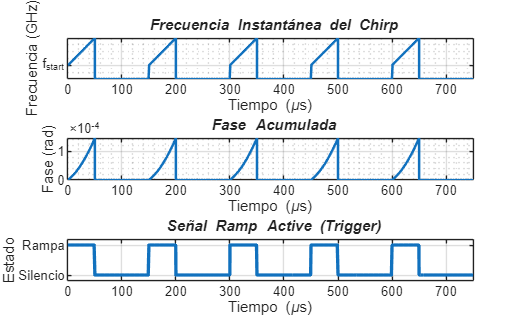


% Crear figura
figure('Position', [100 100 1400 900], 'Name', 'Análisis Radar CW-FM');
subplot(3,1,1);
plot(t*1e6, freq/1e9, 'LineWidth', 1.5);
xlabel('Tiempo (\mus)'); ylabel('Frecuencia (GHz)');
title('\it Frecuencia Instantánea del Chirp');
xlim([0 750]);
yticks([f_start/1e9 f_stop/1e9]); 
yticklabels({'f_{start}','f_{stop}'});
grid on; grid minor;

subplot(3,1,2);
plot(t*1e6, fase_hw, 'LineWidth', 1.5);
xlabel('Tiempo (\mus)'); ylabel('Fase (rad)');
title('\it Fase Acumulada');
xlim([0 750]);
grid on; grid minor;

subplot(3,1,3);
plot(t*1e6, trigger, 'LineWidth', 2);
xlabel('Tiempo (\mus)'); ylabel('Estado');
title('\it Señal Ramp Active (Trigger)');
xlim([0 750]);
ylim([-0.2 1.2]); yticks([0 1]); yticklabels({'Silencio','Rampa'});
grid on;


fprintf('\nEstadísticas:\n');


Estadísticas:


fprintf(' Duración total: %.2f us\n', max(t)*1e6);

 Duración total: 750.00 us


fprintf(' Ancho de banda: %.2f MHz\n', (f_stop - f_start)/1e6);

 Ancho de banda: 2000.00 MHz


fprintf(' Tasa de barrido: %.2f MHz/us\n', (f_stop - f_start)/t_ramp/1e6);

 Tasa de barrido: 40000000.00 MHz/us
